# Chapter 10 ATAP Exercises

## Best Approximation

#### Mason Mault June 2025

Exercises worked

Exercise 10.1: A function with spikes

Exercise 10.2: Best approximation of |x| 

Exercise 10.10: Alternative proof of uniqueness

Exercise 10.12: Every best approximant is an interpolant

**Exercise 10.1: A function with spikes**

Compare the best degree 10 approximation to $f\left(x\right)=\sech^2 \left(5\left(x+0\ldotp 6\right)\right)+\sech^4 \left(50\left(x+0\ldotp 2\right)\right)+\sech^6 \left(500\left(x-0\ldotp 2\right)\right)$ and compare its performance with the 11 point Chebyshev interpolation.

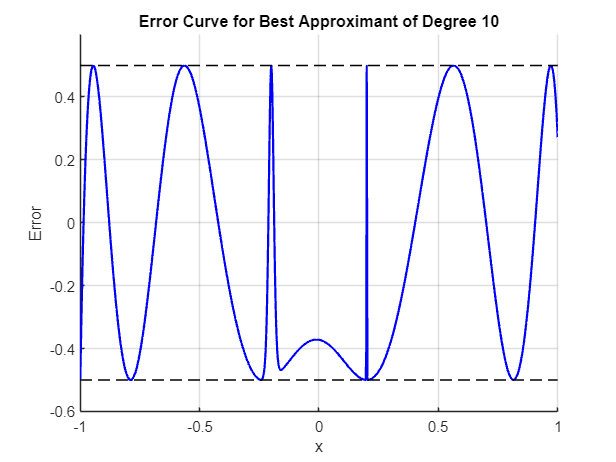

x = chebfun('x');
f = (sech(5*(x + 0.6)))^2 + (sech(50*(x + 0.2)))^4 + (sech(500*(x - 0.2)))^6;

[p10, errP10] = minimax(f, 10);

figure
hold on
plot(f - p10, 'b-', 'LineWidth', 1.5);                       % error curve
plot([-1 1],  errP10 * [1 1], '--k', 'LineWidth', 1);        % +max error line
plot([-1 1], -errP10 * [1 1], '--k', 'LineWidth', 1);        % -max error line

grid on;
xlabel('x');
ylabel('Error');
title('Error Curve for Best Approximant of Degree 10');
ylim([-0.6, 0.6])

Repeat the process for the 11 degreee Chebyshev interpolant

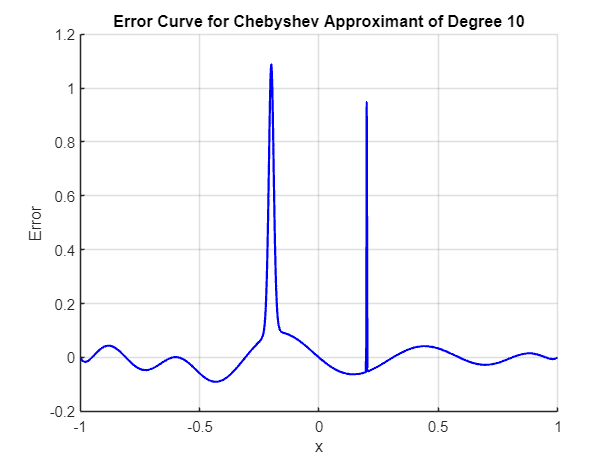

f10 = chebfun(f, 11);

figure
hold on
plot(f - f10, 'b-', 'LineWidth', 1.5);                 

grid on;
xlabel('x');
ylabel('Error');
title('Error Curve for Chebyshev Approximant of Degree 10');

Integrate the absolute value of the error to find the "total" error for both approximations

intp10 = sum(abs(f - p10))

intp10 = 0.6805

intf10 = sum(abs(f - f10))

intf10 = 0.0957

Infinity norm for both approximants to confirm p10 as "best"

infNormp10 = norm(f - p10, inf)

infNormp10 = 0.4999

infNormf10 = norm(f - f10, inf)

infNormf10 = 1.0871

For both approximants, taking the integral of the absolute value and the $L_{\infty }$ norm of the error curve show that the "best" interpolant depends on the measurement tool. The polynomial $p_{10}$, obtained using chebfuns minimax function, is the best in terms of the $L_{\infty }$ norm. However, the Chebyshev interpolant $f_{10}$ is the best approximation in terms of total error over [-1, 1], as measured by the $L_1$ norm.

**Exercise 10.2: Best approximation of |x| **

Determine the errors $E_n =|f-p_n |$in the degree n best approximation of $g\left(x\right)=|x|$on [-1, 1] for n = 2,...256 and make a table of the values $\beta_n ={n\;E}_n$, a scaled version of the error.

g = chebfun(@(x) abs(x));

% initialization 
list = round(2.^linspace(1, 8, 10));
err = zeros(length(list), 1);
beta = zeros(length(list), 1);

% compute best approximant and error at each value of list
for j = 1:length(list)
    i = list(j);
    n = i - 1;
    [pn, err(j)] = minimax(f, n);
    % build and measure error on grid of 2n points
    x = chebpts(2*n);
    err(j) = norm(pn(x) - g(x), inf);
    % append beta
    beta(j) = n*err(j);
end

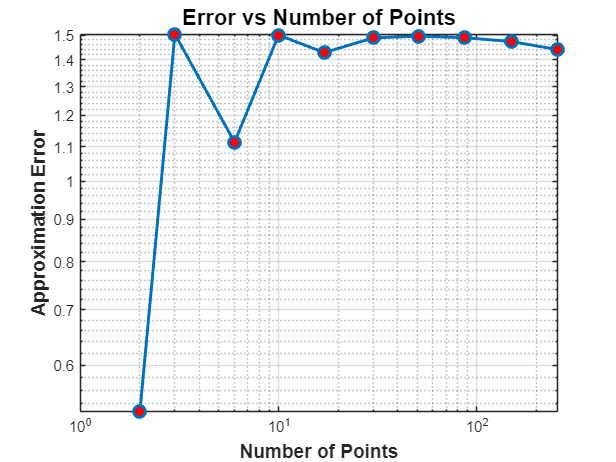


figure
loglog(list, err, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'Color', [0 0.4470 0.7410]);
grid on

xlabel('Number of Points', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Approximation Error', 'FontSize', 13, 'FontWeight', 'bold');
title('Error vs Number of Points', 'FontSize', 15, 'FontWeight', 'bold');

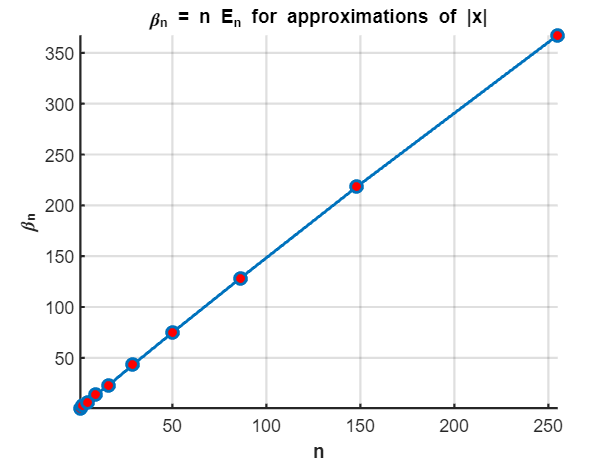

figure;
hold on; grid on;

plot(list - 1, beta, '-o', 'LineWidth', 2, 'MarkerSize', 8, ...
    'MarkerFaceColor', 'r', 'Color', [0 0.4470 0.7410]);

xlabel('n', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('\beta_n', 'FontSize', 14, 'FontWeight', 'bold');
title('\beta_n = n E_n for approximations of |x|', ...
    'FontSize', 16, 'FontWeight', 'bold');

set(gca, 'FontSize', 12, 'LineWidth', 1.5);
axis tight;

**Exercise 10.10: Alternative proof of uniqueness**

Prove uniqueness of the degree $n$ best approximant to a real continuous function $f$ by a simpler argument than the one given in the proof of Theorem 10.1 by supposing $p$ and $q$ are best approximants, and applying the equioscillation characterization argument to $r=\left(p+q\right)/2$.

Theorem 10.1 states a continuous function on [-1, 1] has a unique best approximation $p^* \in P_n$. If the function is real, then $p^*$ is real too, and a polynomial $p$ is equal to $p^*$ iff $|f-p|\;$equioscillates in at least $n+2$ extreme points. 

[Proof]

Suppose $p$ and $q$ are best approximants in $P_n$ to a real continuous function $f$, that $p\not= q$, and that $r=\left(p+q\right)/2$ is also a best approximant to $f$. If $E\;$is the absolute value of the maximum equioscillation amplitude, then both $|f-p|$ and $|f-q|=E$.


$$|f-r|=|f-\frac{p+q}{2}|=|\frac{2f-\left(p+q\right)}{2}|=|\frac{\left(f-p\right)+\left(f-q\right)}{2}|\le \frac{|f-p|+|f-q|}{2}=E$$


which gives 


$$|f-r|\le E$$


for $r$ to be a best approximant, it must be $|f-r|=E\ldotp$ For equality to take place, it must be that $p=q$, making the best approximant unique. 

**Exercise 10.12: Every best approximant is an interpolant**

Let $p$ be the best approximant in $P_n$ to a real function $f\in C\left(\left\lbrack -1,1\right\rbrack \right)$. Show that there exist $n+1$ distinct points $-1<x_0 <\;\ldotp \ldotp \ldotp <x_{n\;} <1$ such that $p$ is the interpolant in $P_n$ to $f$.

[Proof]

By assumption, $p$ is the best approximant to $f$$\in$$P_n$. By Theorem 10.1, there exist at least $n+2$ points ($\left.-1<x_0 <\;\ldotp \ldotp \ldotp <x_{n\;} <1\right)$ where $f-p\;$equioscillates. The $n+2$ equioscillations imply $n+1$ subintervals $\left\lbrack x_j ,x_{j+1} \right\rbrack$. In each subinterval, $f-p$ changes sign, and by the intermediate value theorem, there must be some point where $p=f$. Thus, $p$ interpolates $f$ at $n+1$ distinct points.